# Extract image and audio from video

% read a video file
clear;
vid = VideoReader('bridgeOfSpiesNeutral.mp4');

% Extract images form the video file
i = 0

i = 0

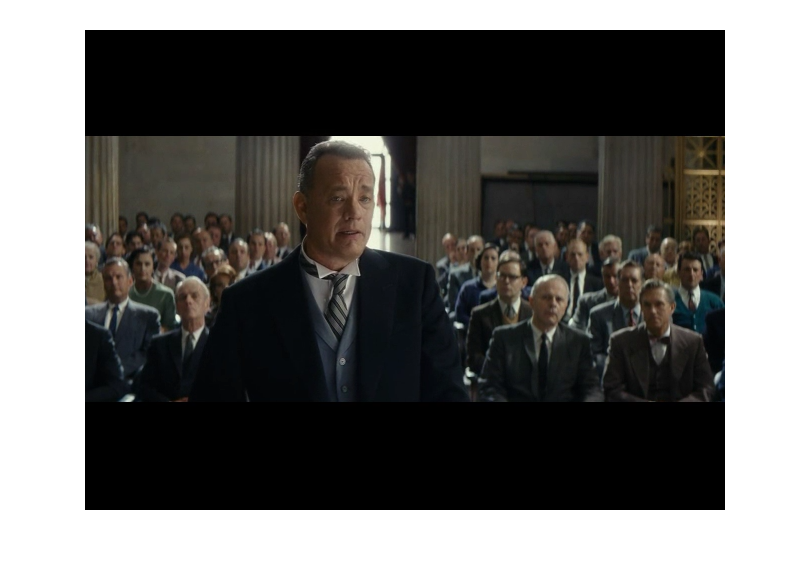

while hasFrame(vid)
    frame = readFrame(vid);
    ii = string(i);
    name = string("scene");
    ext = string(".png");
    new_name = strcat(name,ii,ext);
    new_name_1 = char(new_name);
    imwrite(frame, new_name_1);
    i = i + 1;   
end

% Extract audio from the video file
[input_file, Fs] = audioread('bridgeOfSpiesNeutral.mp4');
audiowrite('outputfile.wav',input_file,Fs);